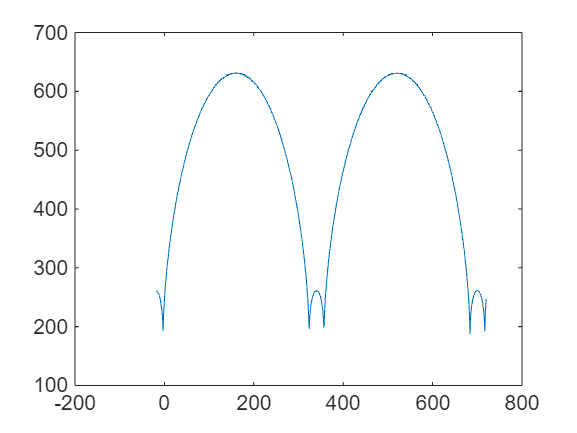

clc
clear
% for k = 1:N
%     M(1,k) = 0 + (k-1)*pi/180*18; % initial phase 
% end
phi=linspace(-18,720,1000);
for i=1:length(phi)
    a=Satellite(phi(i));
    a=a.set_time_parameters(1,1);
    a=a.cal_tau();

    tau(1,i)=sum(a.tau)*(a.h/a.days);
end
plot(phi,tau)

% a=Satellite(-20);
% sum(a.tau)*(a.h/a.days)
% 
% 360/15